clear all;
clc;
close all;

bag = ros2bagreader('test_const_vel/test_soft_3/');
% bag_force_z = select(bag,"Topic","/force_z");
% bag_position_desired = select(bag,"Topic","/position_desired");
% bag_position_real = select(bag,"Topic","/position_real");
% bag_surface = select(bag,"Topic","/surface");
bag_data = select(bag,"Topic","/data_control");

bag_ft2 = select(bag,"Topic","/force_torque_sensor_broadcaster/wrench");
bag_ft = select(bag,"Topic","/bus0/ft_sensor0/ft_sensor_readings/wrench");
% bag_time = select(bag,"Topic","/clock");

% mes_force_z = readMessages(bag_force_z);
% mes_position_desired = readMessages(bag_position_desired);
% mes_position_real = readMessages(bag_position_real);
% mes_surface = readMessages(bag_surface);
mes_data = readMessages(bag_data);
mes_ft = readMessages(bag_ft);
mes_ft2 = readMessages(bag_ft2);
% mes_time = readMessages(bag_time);
n_mess = bag_data.NumMessages;
% n_v = bag_position_desired.NumMessages;
% n_f = bag_position_real.NumMessages;
n_ft = bag_ft.NumMessages;
n_ft2 = bag_ft2.NumMessages;
%st = min([n_u,n_v,n_f])

sim_time = zeros(n_mess,1);
for i = 1:n_mess
    sim_time(i) =  mes_data{i, 1}.data(1);  
end
initial_time = sim_time(1);
sim_time(:) = sim_time(:)-initial_time;
dT = sim_time(2)

dT = 0.0020


force_z = zeros(n_mess,1);
for i = 1:n_mess
    force_z(i) =  -mes_data{i, 1}.data(6);  
end
% 
% ft = zeros(n_ft,2);
% k=0;
% ft(1,1) =  -mes_ft{1, 1}.wrench.force.z;  
% ft(1,2) = double(mes_ft{1, 1}.header.stamp.sec) + double(mes_ft{1, 1}.header.stamp.nanosec)*1.0e-9;
% for i = 2:n_ft
%     if double(mes_ft{i, 1}.header.stamp.sec) + double(mes_ft{i, 1}.header.stamp.nanosec)*1.0e-9 - ft(1,2) > 0
%         ft(i-k,1) =  -mes_ft{i, 1}.wrench.force.z;  
%         ft(i-k,2) = double(mes_ft{i, 1}.header.stamp.sec) + double(mes_ft{i, 1}.header.stamp.nanosec)*1.0e-9;
%     else 
%         k=k+1;
%     end
% end
% ft(:,2) = ft(:,2) - initial_time;
% 
% ft2 = zeros(n_ft2,2);
% k=0;
% ft2(1,1) =  -mes_ft2{1, 1}.wrench.force.z;  
% ft2(1,2) = double(mes_ft2{1, 1}.header.stamp.sec) + double(mes_ft2{1, 1}.header.stamp.nanosec)*1.0e-9;
% for i = 2:n_ft2
%     if double(mes_ft2{i, 1}.header.stamp.sec) + double(mes_ft2{i, 1}.header.stamp.nanosec)*1.0e-9 - ft2(1,2) > 0
%         ft2(i-k,1) =  -mes_ft2{i, 1}.wrench.force.z;  
%         ft2(i-k,2) = double(mes_ft2{i, 1}.header.stamp.sec) + double(mes_ft2{i, 1}.header.stamp.nanosec)*1.0e-9;
%     else 
%         k=k+1;
%     end
% end
% ft2(:,2) = ft2(:,2) - initial_time;

mean_force_z = mean(force_z(1:2000))

mean_force_z = 7.2588

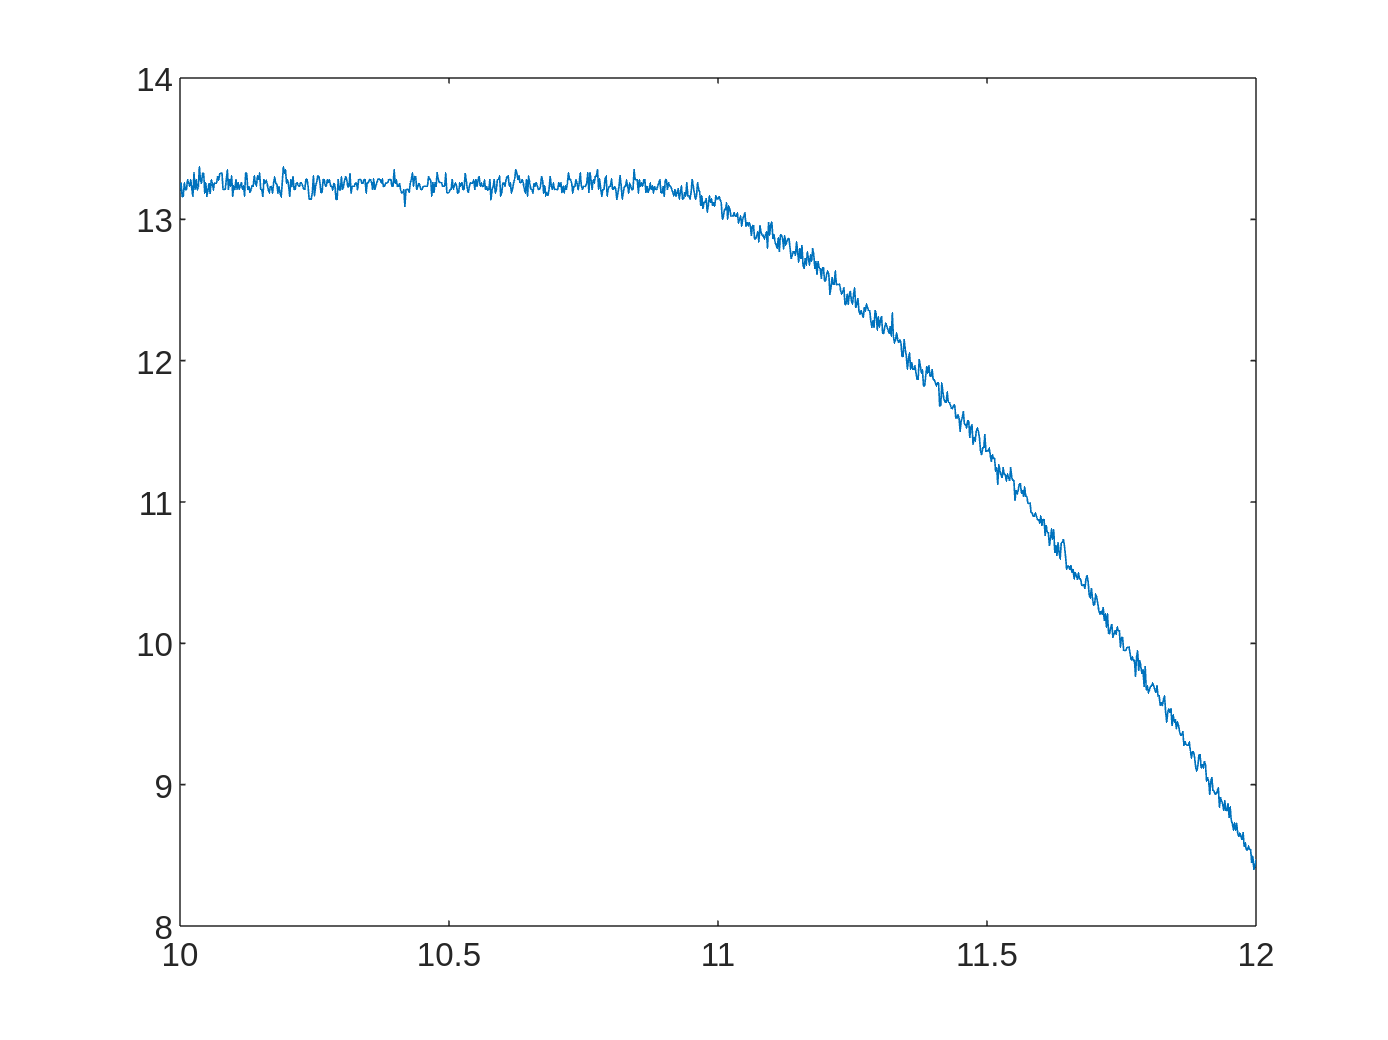





plot(sim_time,force_z)
hold on 
%plot(ft2(:,2),ft2(:,1))
%plot(ft(:,2),ft(:,1))
hold off
xlim([10,12])

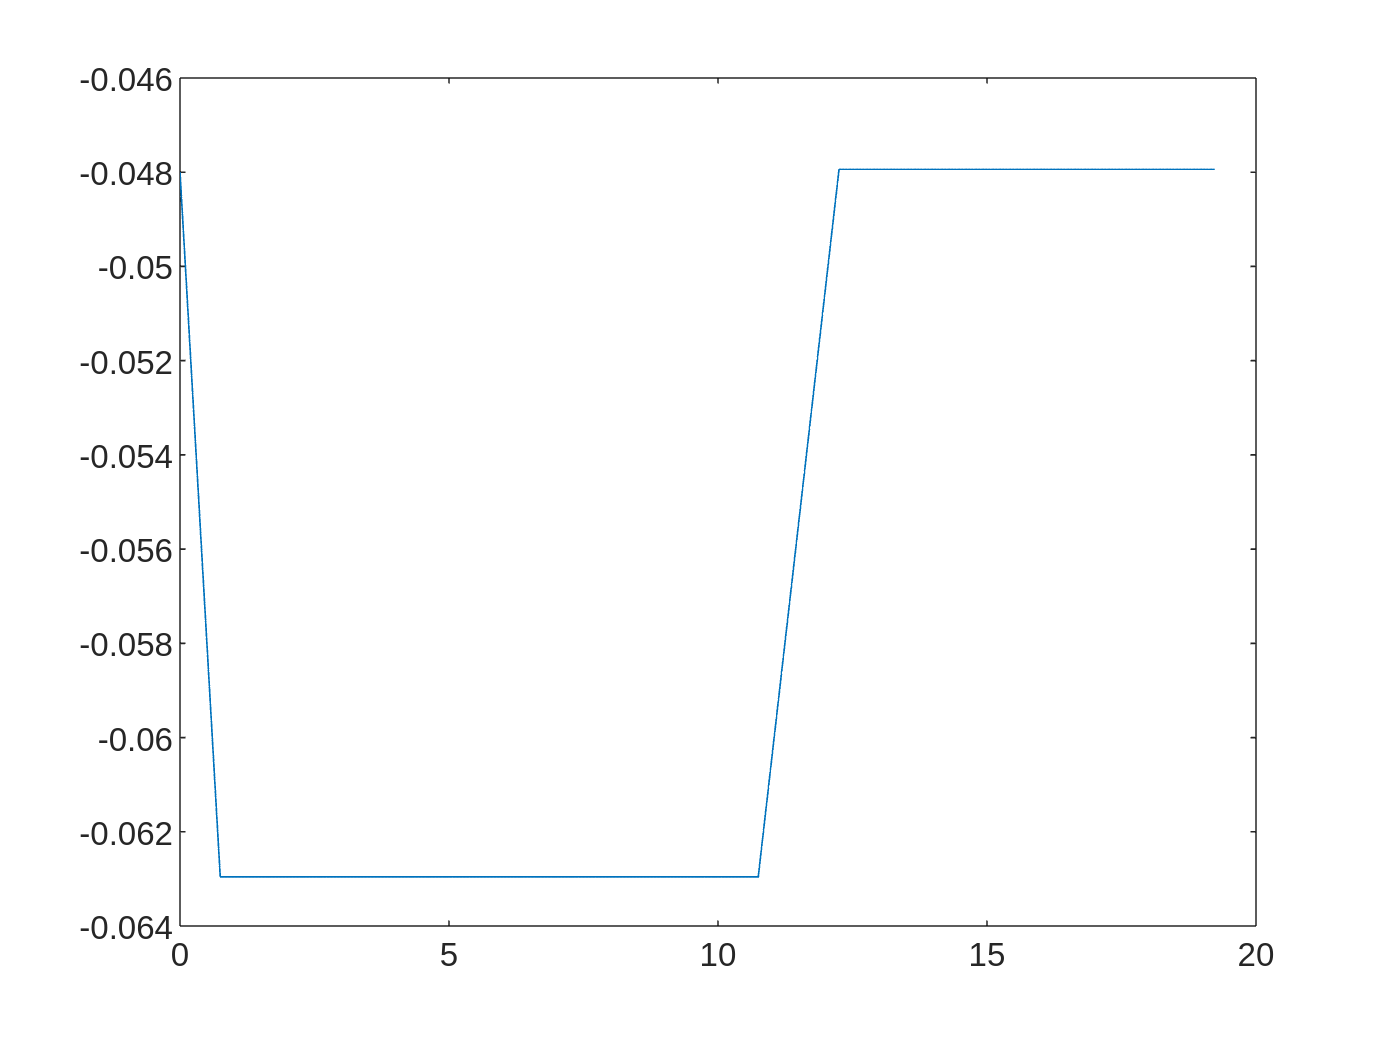


position_desired = zeros(n_mess,1);
for i = 1:n_mess
    position_desired(i) =  mes_data{i, 1}.data(3);
end

plot(sim_time(:),position_desired(:))

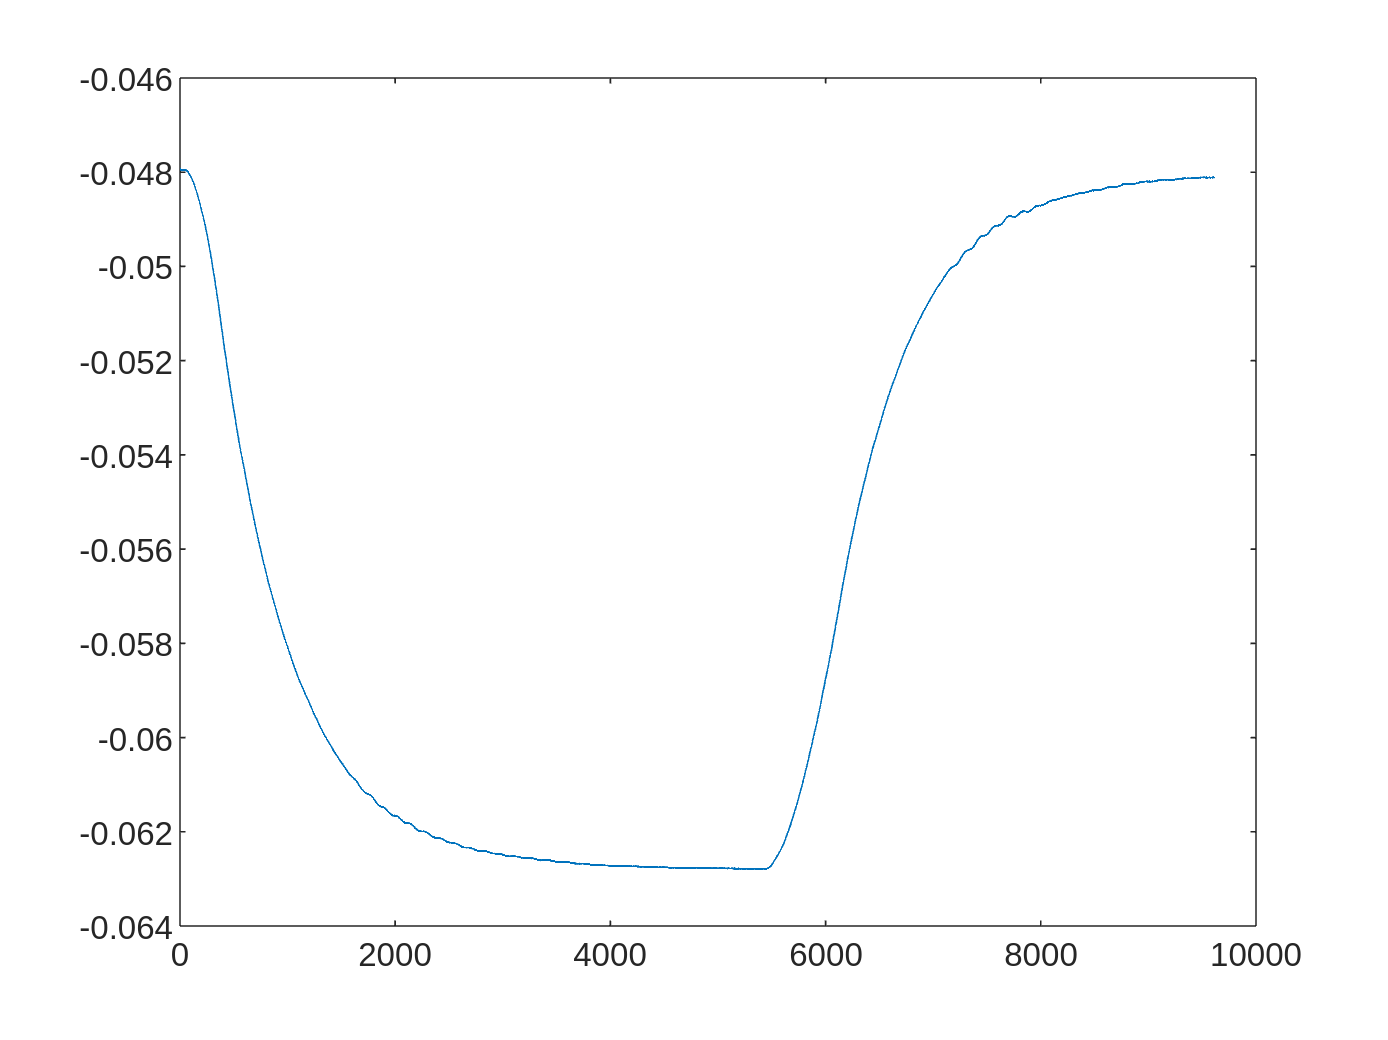


position_real = zeros(n_mess,1);
for i = 1:n_mess
    position_real(i) =  mes_data{i, 1}.data(4);  
end

plot(position_real(:))

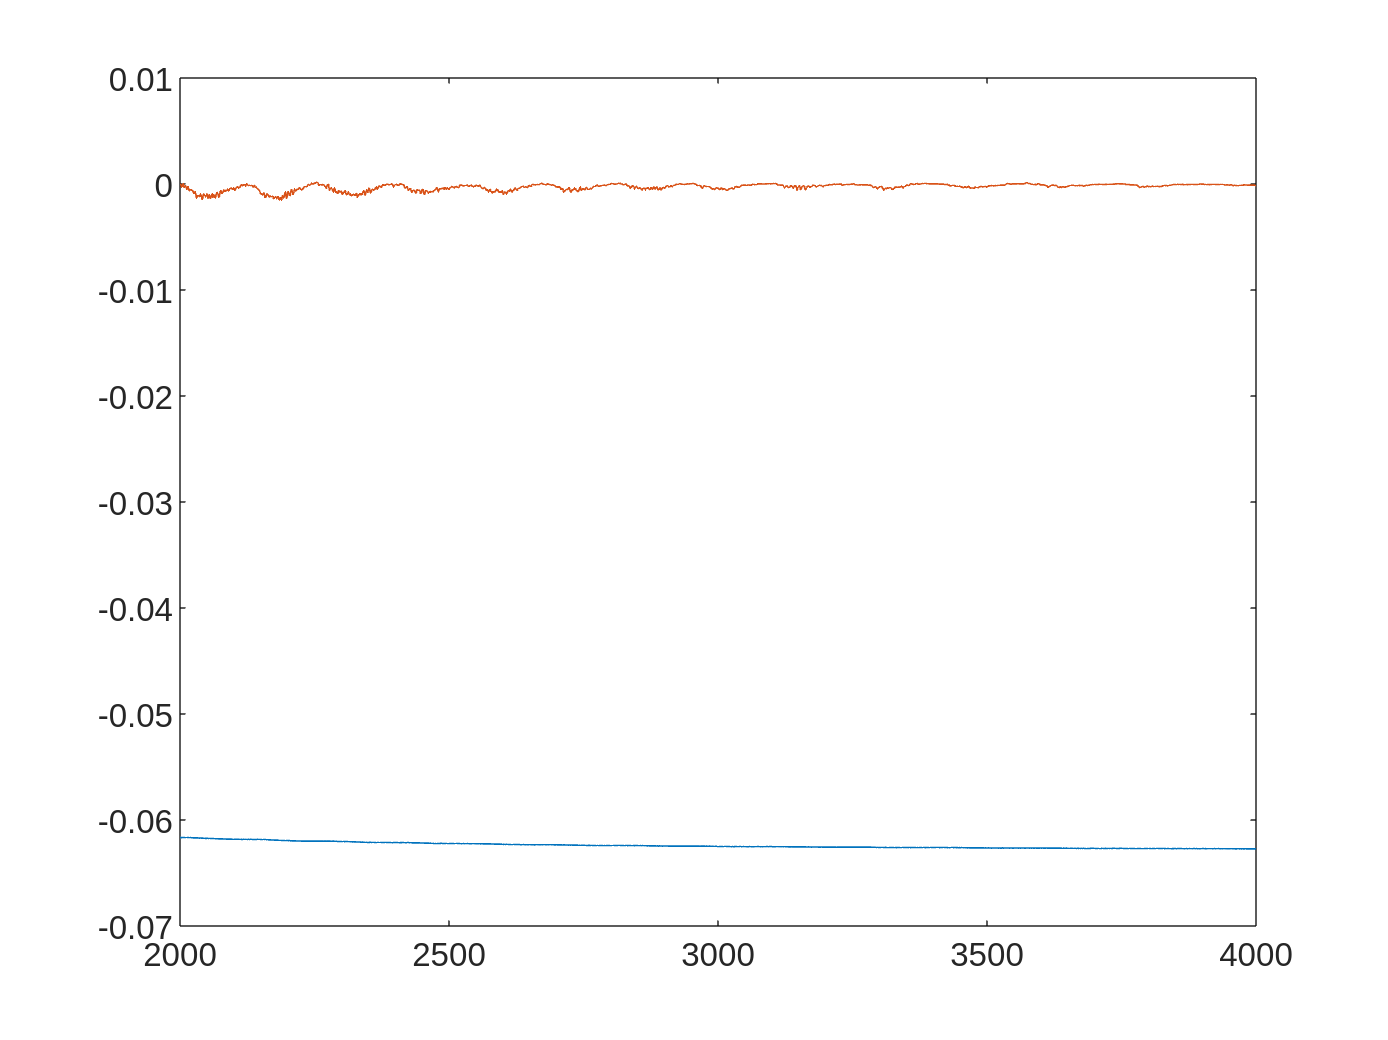

velocity_z = zeros(n_mess,1);
for i = 1:n_mess
    velocity_z(i) =  mes_data{i, 1}.data(5);  
end

plot([position_real,velocity_z])
xlim([2000,4000])

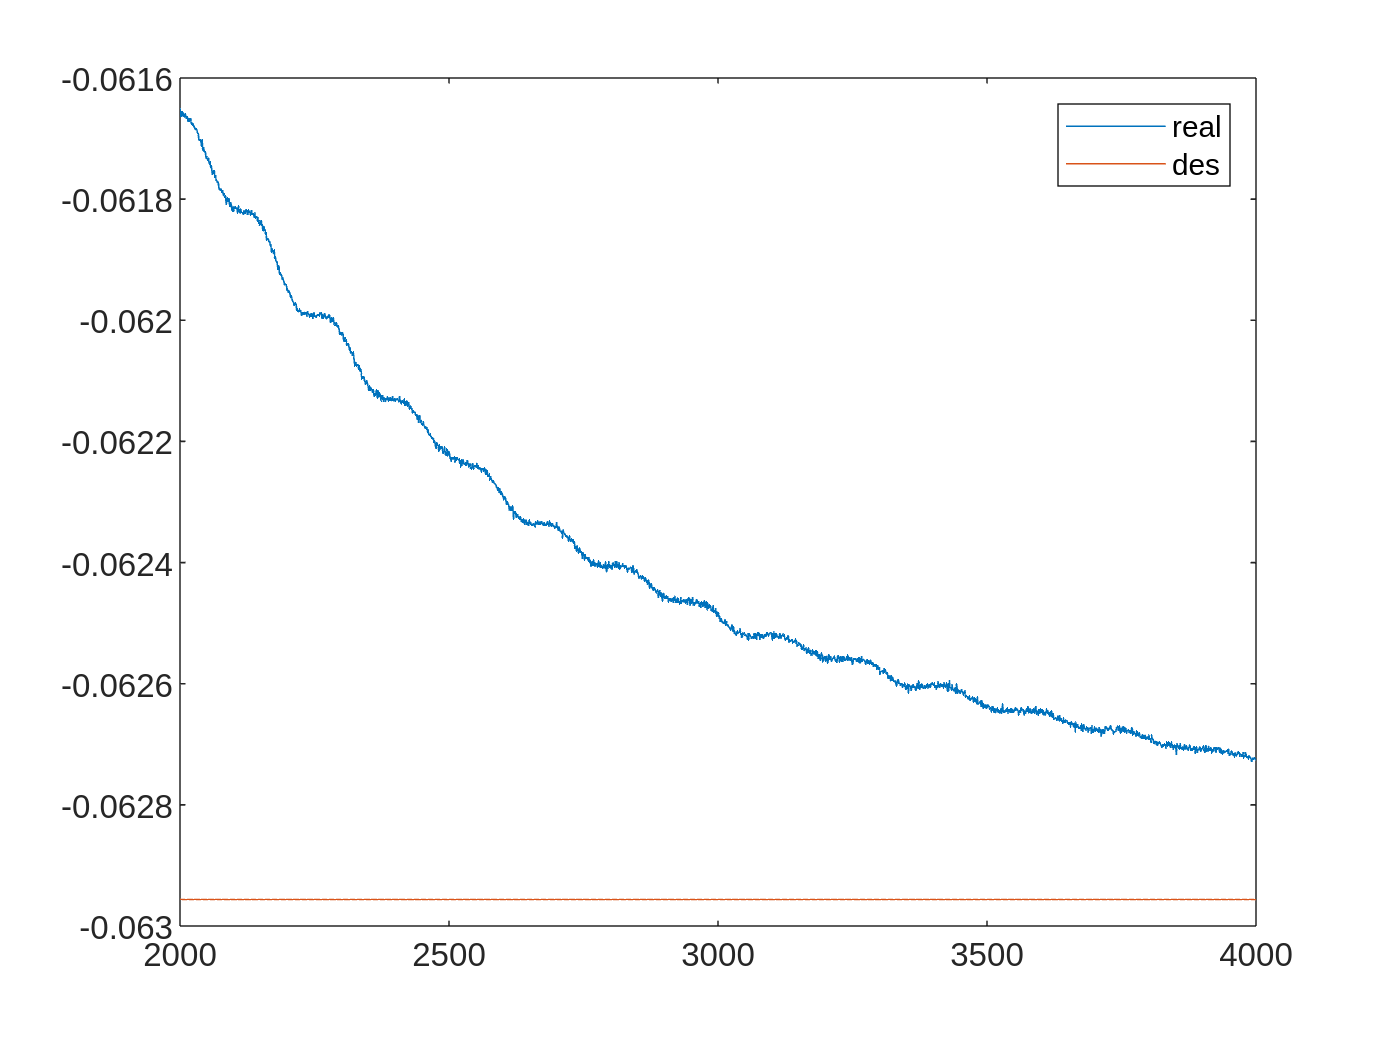

plot(position_real)
hold on 
plot(position_desired)
hold off
xlim([2000,4000])
legend(["real","des"])

surface_high = mes_data{1,1}.data(2)

surface_high = -0.0480

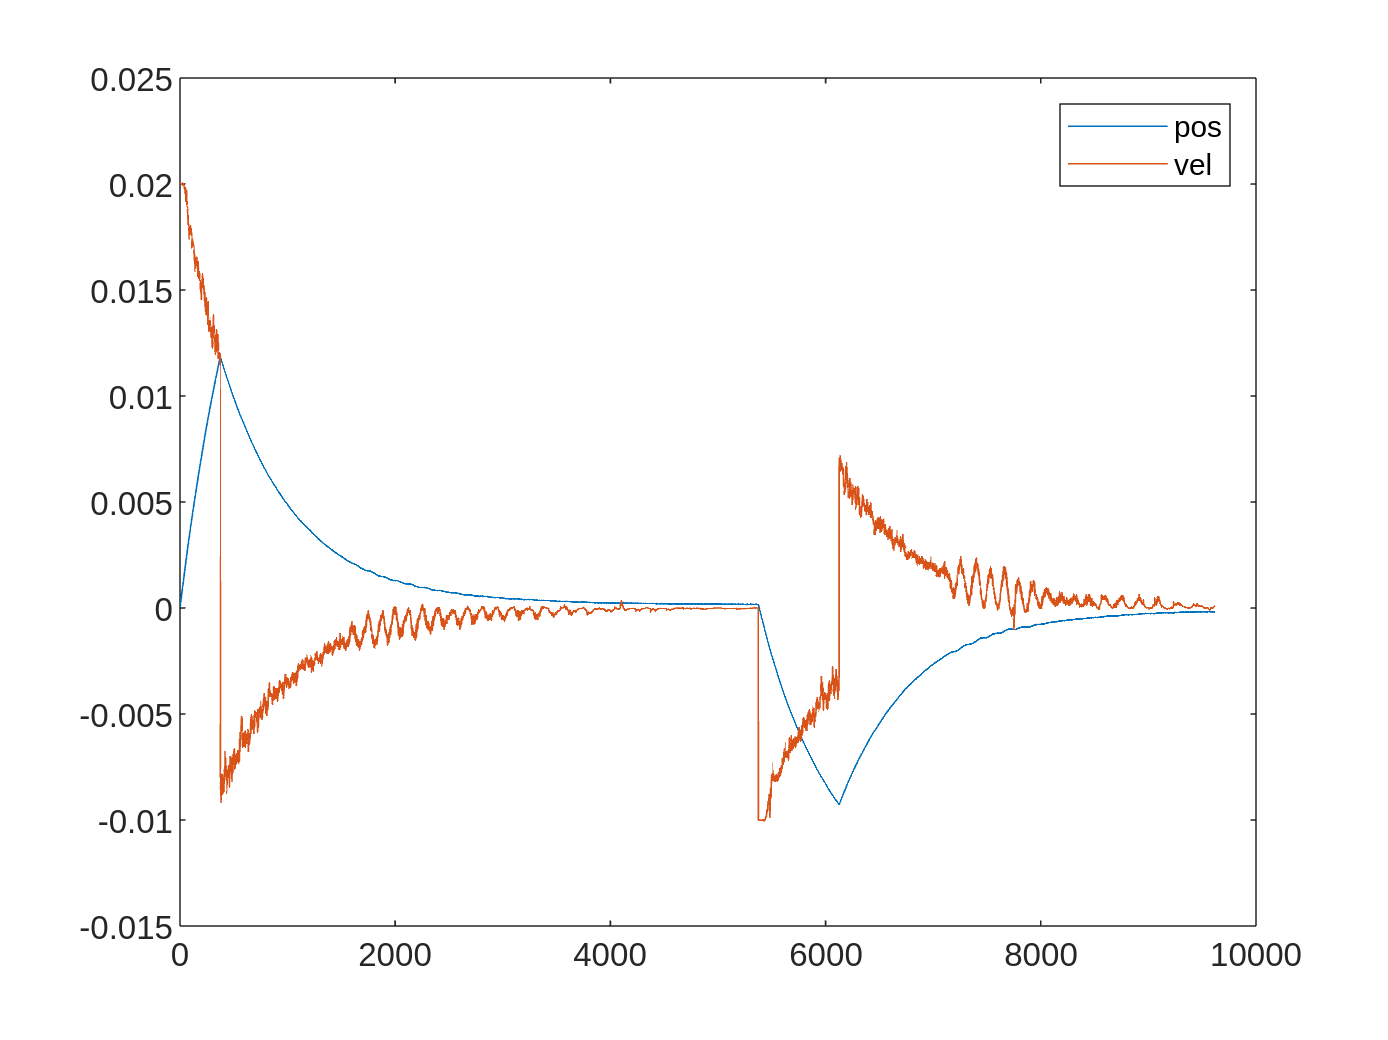

u = position_real-position_desired;
up = zeros(n_mess,1);
up(1:n_mess-1) = velocity_z(1:end-1) - diff(position_desired)/(dT);
up(n_mess)=up(n_mess-1);
upp = zeros(n_mess,1);
upp(1:n_mess-1) = diff(up)/(dT);
upp(n_mess)=upp(n_mess-1);
plot(u)
hold on 
plot(up)
hold off
legend(["pos","vel"])

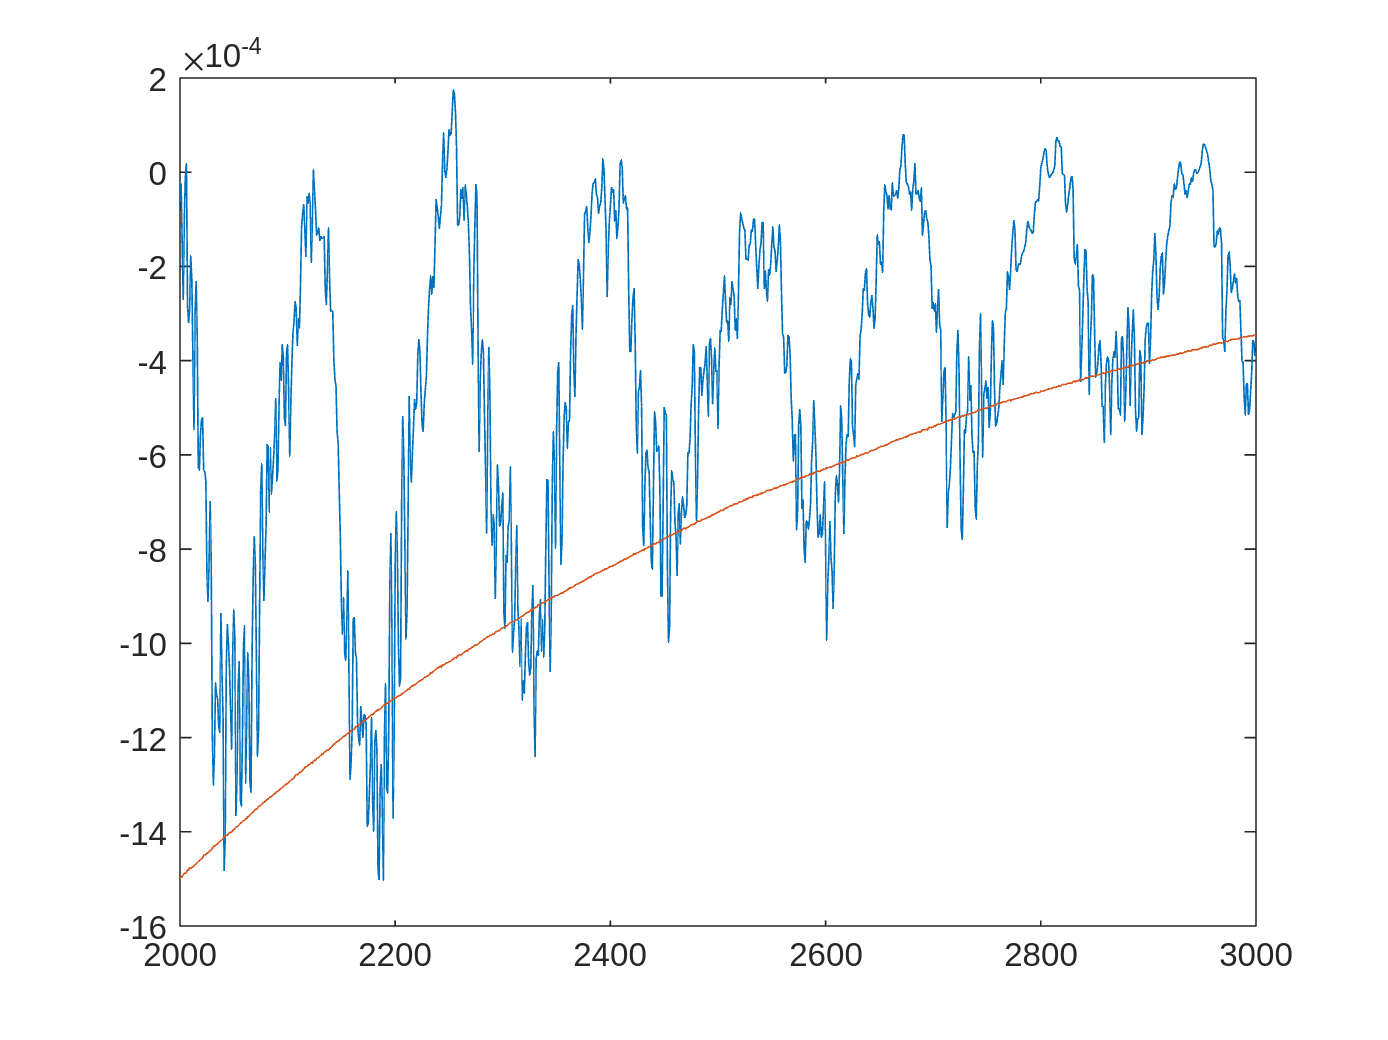

xp = zeros(n_mess,1);
xp(1:n_mess-1) = diff(smoothdata(position_real))/(dT);
xp(n_mess)=xp(n_mess-1);
xpp = zeros(n_mess,1);
xpp(1:n_mess-1) = diff(xp)/(dT);
xpp(n_mess)=xpp(n_mess-1);
plot([velocity_z,xp])
xlim([2000,3000])

% force_zd = zeros(n_mess,1);
% force_zd(1:n_mess-1) = diff(smoothdata(force_z,"SmoothingFactor",0.3))/(dT);
% force_zd(n_mess)=force_zd(n_mess-1);
% plot(force_zd)

% Fit the model 'z = k * u + c * up'
X = [u(2000:5000),up(2000:5000)];
% mdl = fitlm(X, smoothdata(force_z(2000:5000)), "y~-1+x1+x2");

% Display the regression results
% disp(mdl);
lsqr(X,force_z(2000:5000))

lsqr converged at iteration 2 to a solution with relative residual 0.54.


ans = 1.0e+04 *

    2.5535
    0.9427



% Get the coefficients 'a' and 'b' from the model
% stiffness = mdl.Coefficients.Estimate(1); % Coefficient for 'x'
% damping = mdl.Coefficients.Estimate(2); % Coefficient for 'y'
% mass = mdl.Coefficients.Estimate(3); % Coefficient for 'y'

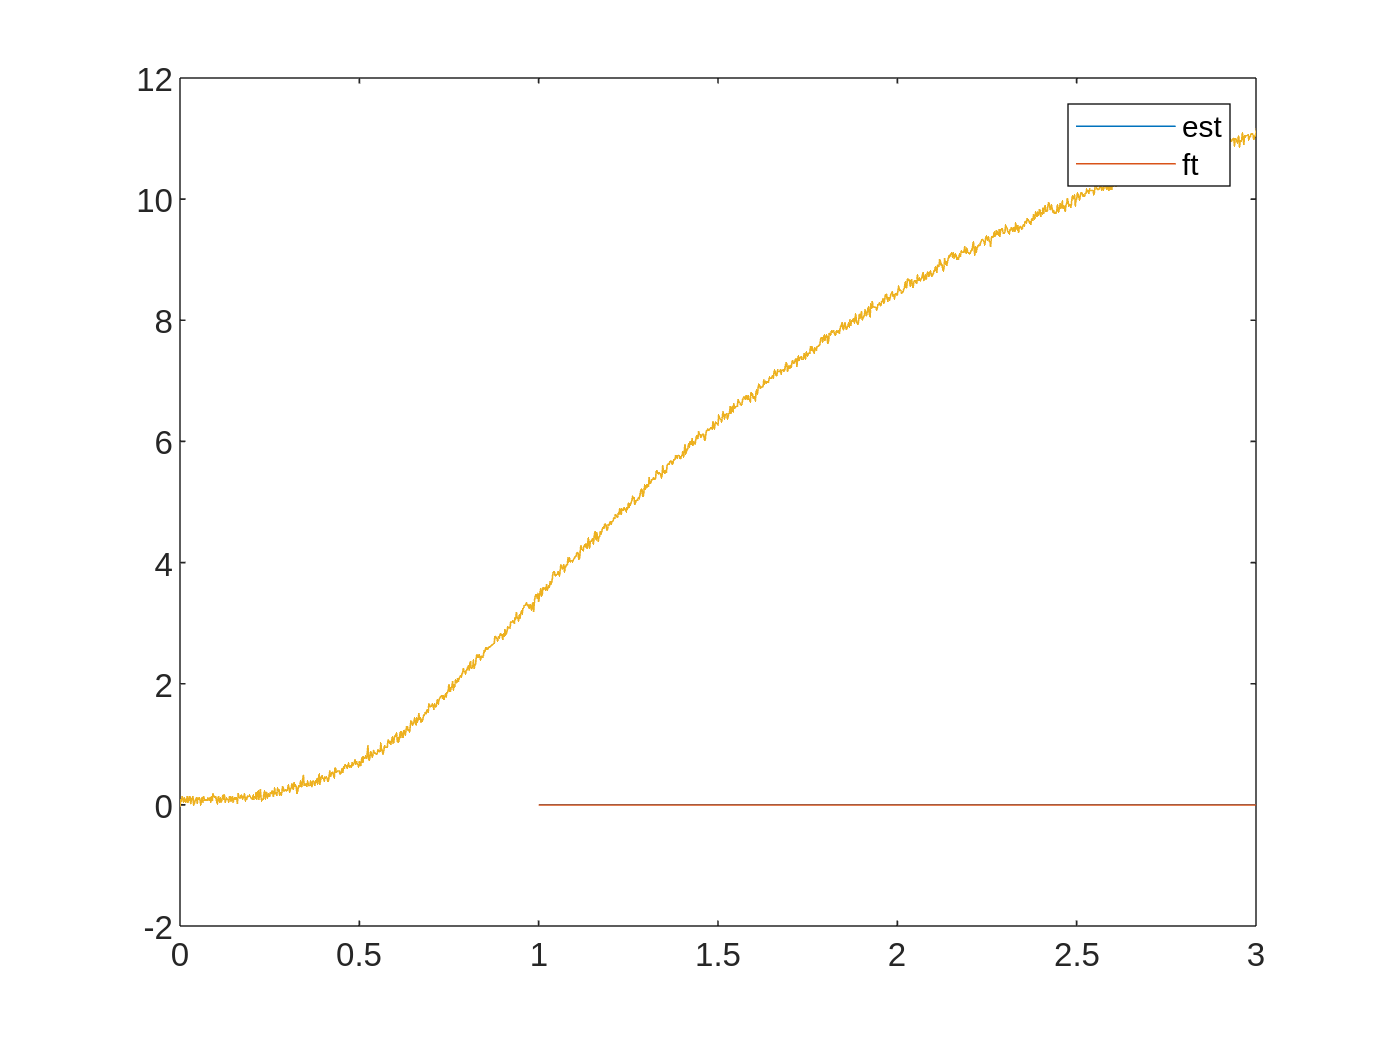


%plot(sim_time,  stiffness*u  + damping*up + mass * xpp)
hold on 
plot(sim_time, force_z)
hold off 
legend(["est","ft"])
xlim([0,3])

tissue_stiffness = (max(force_z(2000:5000))-min(force_z(2000:5000)))/ (max(position_real(2000:5000))-min(position_real(2000:5000)))

tissue_stiffness = 1.0734e+03

surf = max(position_real(2000:5000)) +  min(force_z(2000:5000))/tissue_stiffness

surf = -0.0503

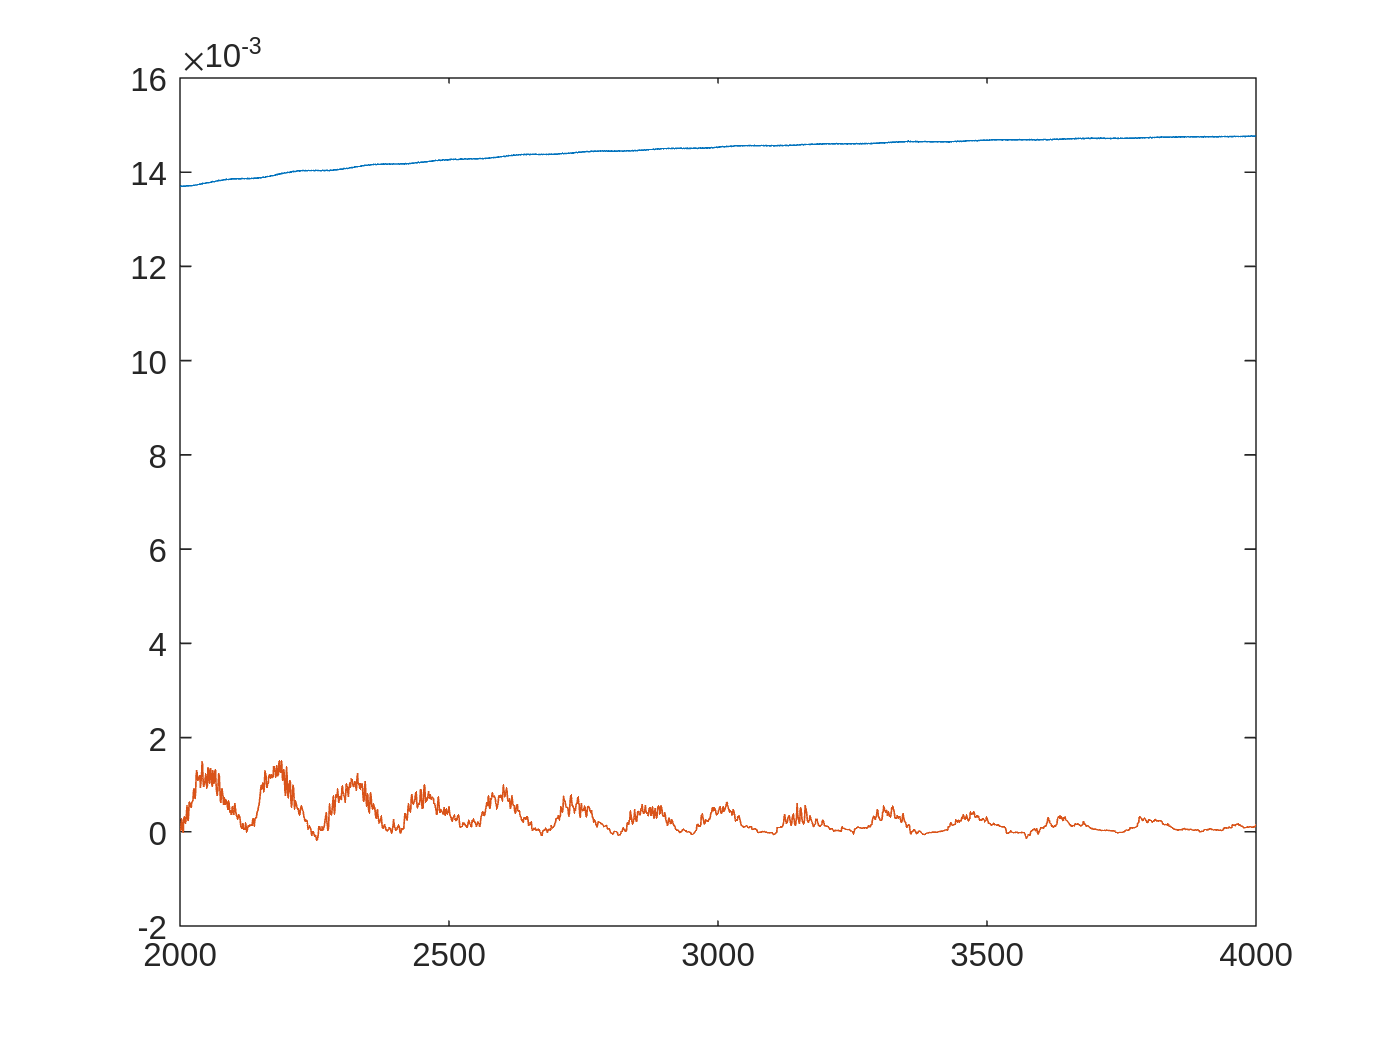


p = surface_high - position_real;
%n_mess = 4000
pp = -velocity_z;
ppp = zeros(n_mess,1);
ppp(1:n_mess-1) = diff(-velocity_z)/(dT);
ppp(n_mess)=ppp(n_mess-1);

plot([p,-velocity_z])
xlim([2000,4000])

force_zp = zeros(n_mess,1);
force_zp(1:n_mess-1) = diff(force_z)/(dT);
force_zp(n_mess)=force_zp(n_mess-1);

%xlim([1,2000])
% Fit the model 'z = k * u + c * up'
X = [abs(p).^(1.2), -velocity_z.*abs(p).^(1.2), ppp(1:n_mess)];
% smooth_force = smoothdata(force_z);
% mdl = fitlm(X, force_z(1:n_mess),'y ~ x1 + x2 + x3 - 1');
% 
% % Display the regression results
% disp(mdl)
lsqr_method = lsqr([p,-velocity_z,ppp],force_z)

lsqr converged at iteration 3 to a solution with relative residual 0.066.


lsqr_method =   878.4494
   63.3042
    0.0103


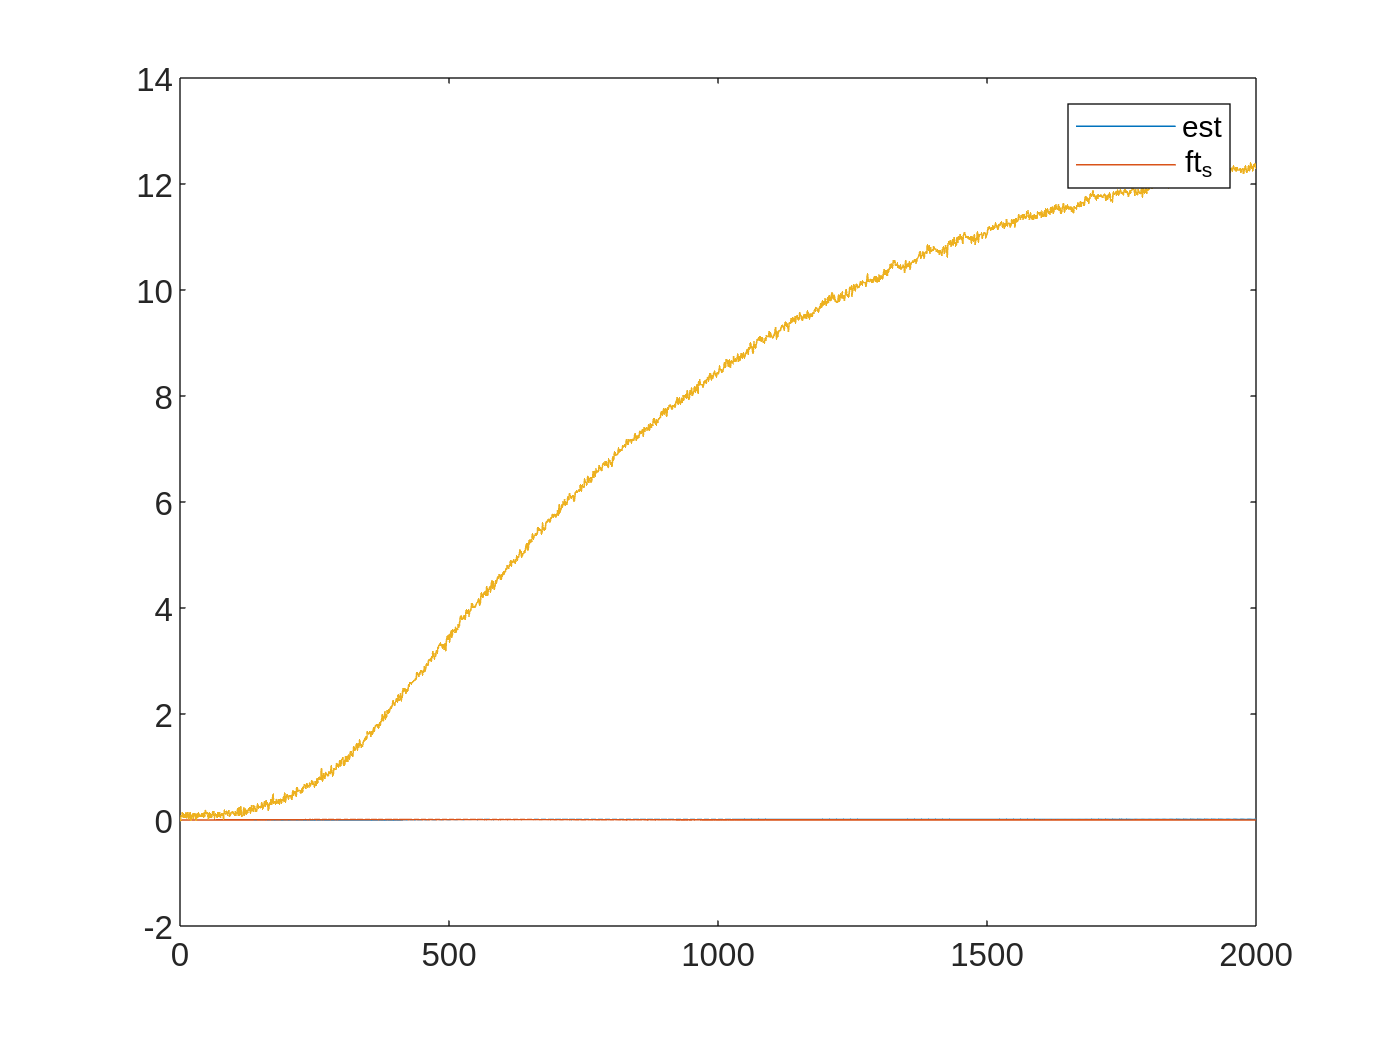


% Get the coefficients 'a' and 'b' from the model
% stiffness = mdl.Coefficients.Estimate(1); % Coefficient for 'x'
% damping = mdl.Coefficients.Estimate(2); % Coefficient for 'y'
% mass = mdl.Coefficients.Estimate(3); % Coefficient for 'y'

% plot(stiffness * p - damping * velocity_z.*p + mass * ppp)
hold on 
plot(force_z)
hold off 
xlim([0,2000])
legend(["est","ft_s"])

% KV model 
KV_coeff = lsqr([p,pp,ppp],force_z)

lsqr converged at iteration 3 to a solution with relative residual 0.066.


KV_coeff =   878.4494
   63.3042
    0.0103


%HC model 
n = 1.5;
HC_coeff5 = lsqr([p(200:end).^(n),-velocity_z(200:end).*p(200:end).^(n),ppp(200:end)],force_z(200:end))

lsqr stopped at iteration 3 without converging to the desired tolerance 1e-06
because the maximum number of iterations was reached.
The iterate returned (number 3) has relative residual 0.029.


HC_coeff5 = 1.0e+04 *

    0.7520
    7.7258
    0.0000


n = 1.35;
HC_coeff4 = lsqr([p(200:end).^(n),-velocity_z(200:end).*p(200:end).^(n),ppp(200:end)],force_z(200:end))

lsqr stopped at iteration 3 without converging to the desired tolerance 1e-06
because the maximum number of iterations was reached.
The iterate returned (number 3) has relative residual 0.014.


HC_coeff4 = 1.0e+04 *

    0.3958
    3.9499
    0.0000



n = 1.3;
HC_coeff3 = lsqr([p(200:end).^(n),-velocity_z(200:end).*p(200:end).^(n),ppp(200:end)],force_z(200:end))

lsqr stopped at iteration 3 without converging to the desired tolerance 1e-06
because the maximum number of iterations was reached.
The iterate returned (number 3) has relative residual 0.015.


HC_coeff3 = 1.0e+04 *

    0.3195
    3.1558
    0.0000


n = 1.2;
HC_coeff2 = lsqr([p(200:end).^(n),-velocity_z(200:end).*p(200:end).^(n),ppp(200:end)],force_z(200:end))

lsqr stopped at iteration 3 without converging to the desired tolerance 1e-06
because the maximum number of iterations was reached.
The iterate returned (number 3) has relative residual 0.027.


HC_coeff2 = 1.0e+04 *

    0.2080
    2.0116
    0.0000



n = 1.1;
HC_coeff1 = lsqr([p(200:end).^(n),-velocity_z(200:end).*p(200:end).^(n),ppp(200:end)],force_z(200:end))

lsqr converged at iteration 3 to a solution with relative residual 0.045.


HC_coeff1 = 1.0e+04 *

    0.1353
    1.2798
    0.0000


%Kelvin-Boltzmann
KB_coeff = lsqr([p,pp,ppp,force_zp],force_z)

lsqr stopped at iteration 4 without converging to the desired tolerance 1e-06
because the maximum number of iterations was reached.
The iterate returned (number 4) has relative residual 0.068.


KB_coeff =   878.4963
    4.4163
   -0.0515
   -0.0006


%Dimentionality-Reduction
DR_coeff = lsqr([p(200:end).^(1.5),pp(200:end).*p(200:end).^(0.5),ppp(200:end)],force_z(200:end))

lsqr converged at iteration 3 to a solution with relative residual 0.029.


DR_coeff = 1.0e+03 *

    7.5205
    0.7766
    0.0001


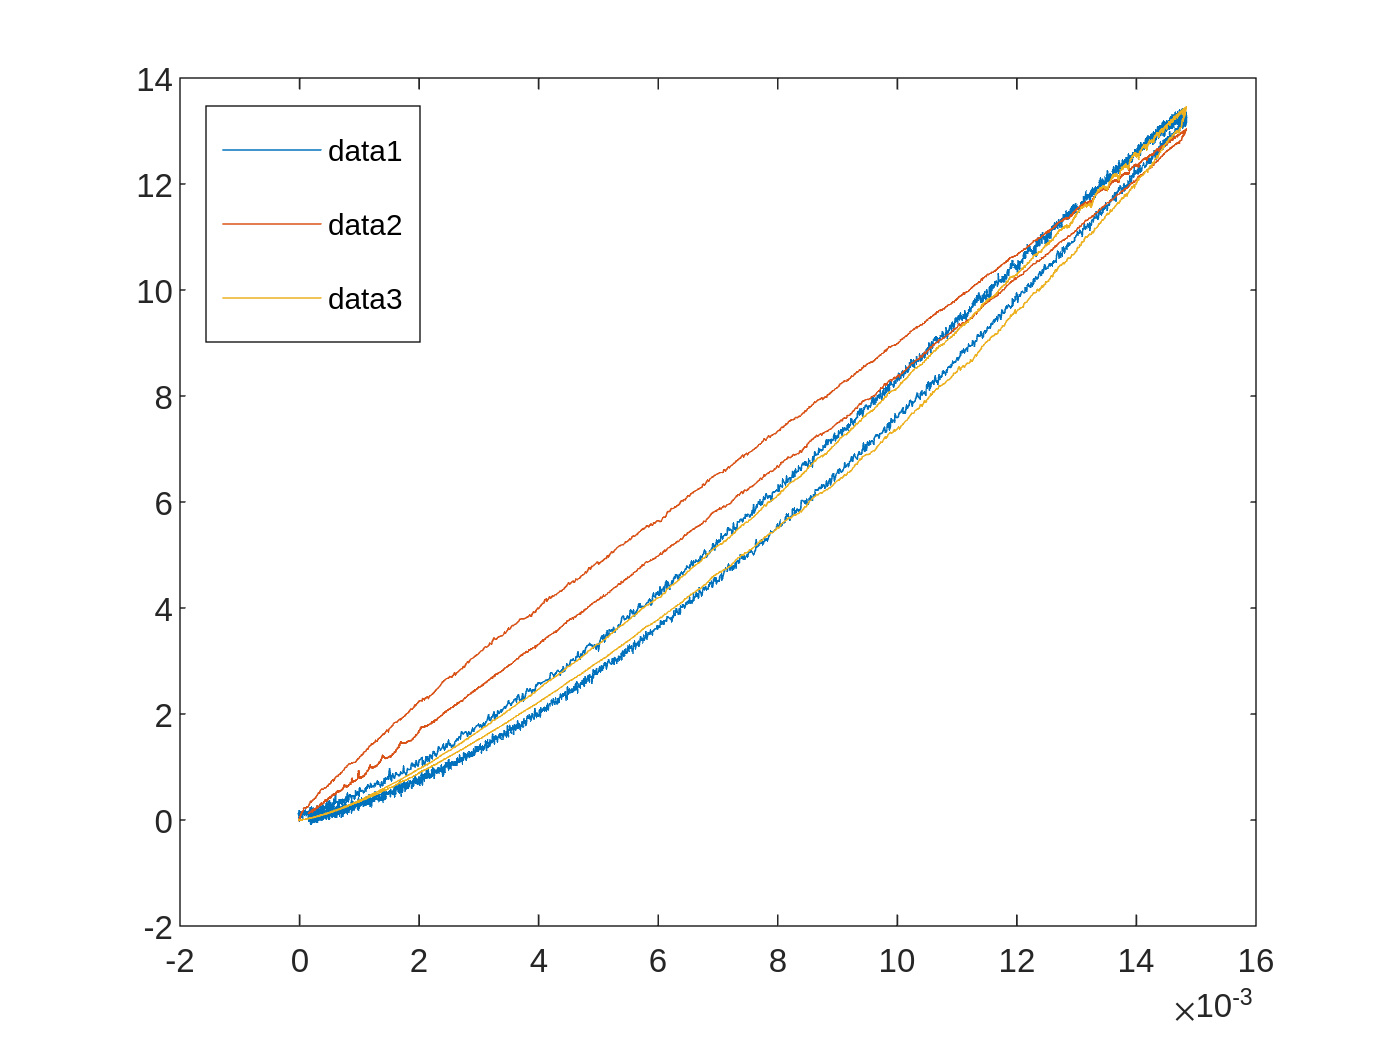

plot(p,force_z)
hold on
plot(p, KV_coeff(1) * p + KV_coeff(2)*pp + KV_coeff(3) * ppp)
% plot(p, HC_coeff5(1) * abs(p).^(1.5) + HC_coeff5(2)*pp.* abs(p).^(1.5) + HC_coeff5(3) * ppp)
plot(p, HC_coeff4(1) * abs(p).^(1.35) + HC_coeff4(2)*pp.* abs(p).^(1.35) + HC_coeff4(3) * ppp)
% plot(p, HC_coeff3(1) * abs(p).^(1.3) + HC_coeff3(2)*pp.* abs(p).^(1.3) + HC_coeff3(3) * ppp)
% plot(p, HC_coeff2(1) * abs(p).^(1.2) + HC_coeff2(2)*pp.* abs(p).^(1.2) + HC_coeff2(3) * ppp)
% plot(p, HC_coeff1(1) * abs(p).^(1.1) + HC_coeff1(2)*pp.* abs(p).^(1.1) + HC_coeff1(3) * ppp)
% plot(p, KB_coeff(1) * p + KB_coeff(2)*pp + KB_coeff(3) * ppp + KB_coeff(4)*force_zp)
% plot(p, DR_coeff(1) * abs(p).^(1.5) + DR_coeff(2)*pp.* abs(p).^(0.5) + DR_coeff(3) * ppp)
hold off
%legend(["ft senosr","KV","HC 1.5","HC 1.3","HC 1.1","KB","DR"])
% legend(["ft senosr","HC 1.5","DR"])

legend("Position", [0.14905,0.67164,0.15385,0.22642])

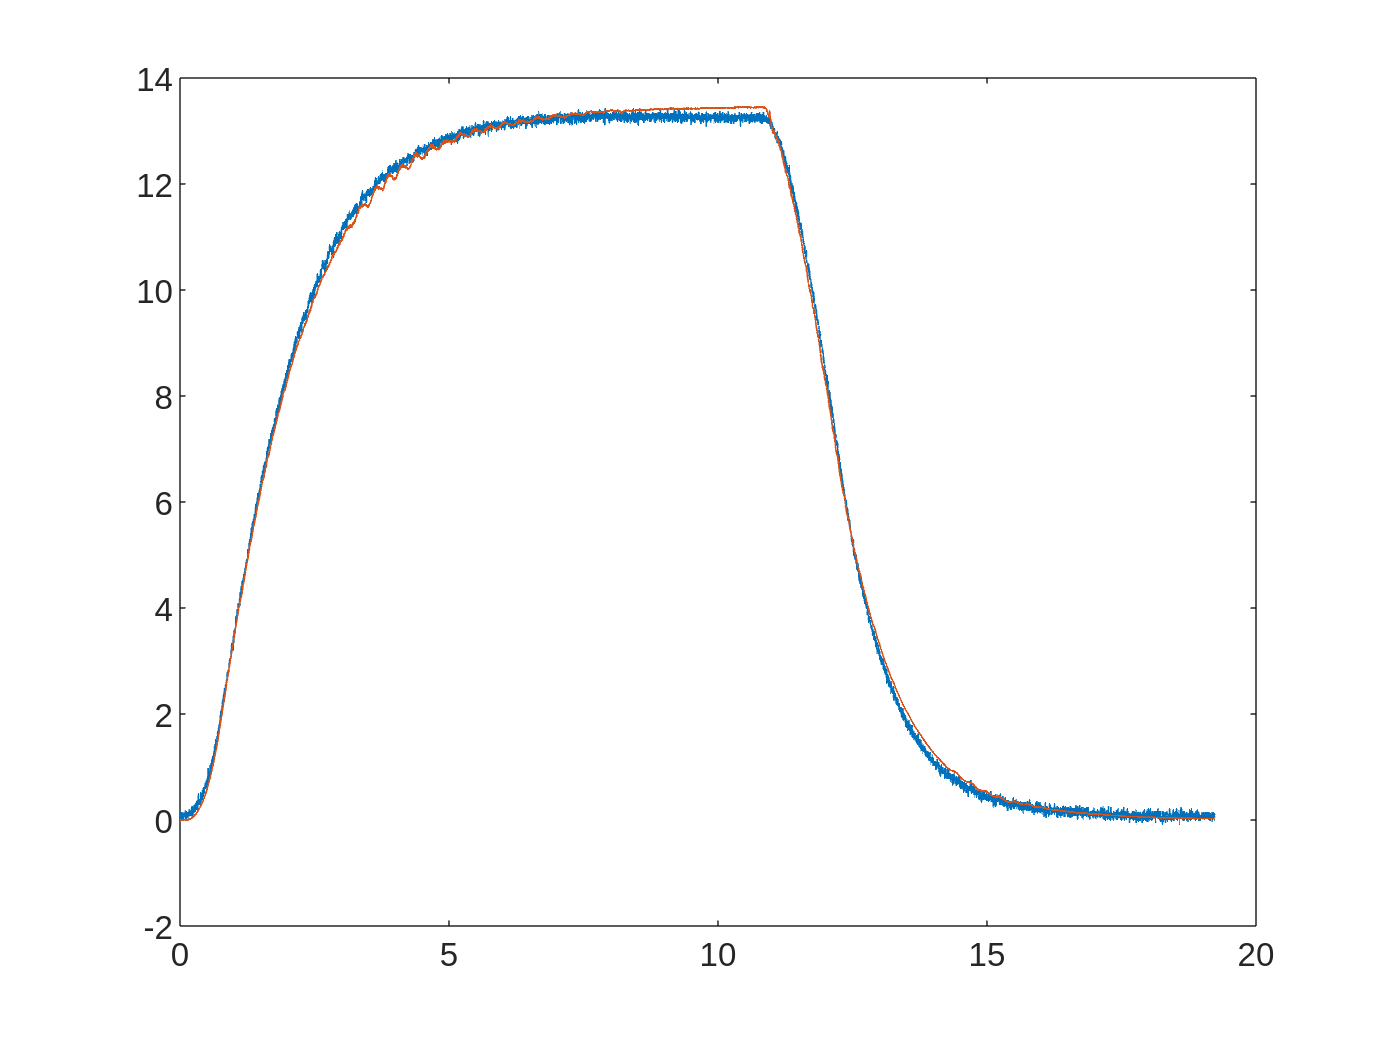

plot(sim_time,force_z)
hold on 
plot(sim_time,HC_coeff4(1) * abs(p).^(1.35) + HC_coeff4(2)*pp.* abs(p).^(1.35) + HC_coeff4(3) * ppp)
hold off

% data_in = up;
% inputData = timeseries(data_in,sim_time);
% save("sim/up.mat","inputData","-v7.3");
% 
% data_in = upp;
% inputData = timeseries(data_in,sim_time);
% save("sim/upp.mat","inputData","-v7.3");
% 
% data_in = u;
% inputData = timeseries(data_in,sim_time);
% save("sim/u.mat","inputData","-v7.3");
% 
% data_in = p;
% inputData = timeseries(data_in,sim_time);
% save("sim/x.mat","inputData","-v7.3");
% 
% data_in = force_z;
% inputData = timeseries(data_in,sim_time);
% save("sim/force.mat","inputData","-v7.3");